%Q1. Lead compensator design 
clc,clearvars;
R = 0.3;
L = 0.45;
l = 0.8;
M = 16;
m = 80;
kT = 0.75;
kbemf = 0.75;
r_a = 1.5;
c1 = 0.1;
c2 = 0.1;
g = 9.81;
alpha = kT/r_a;
beta = (kT*kbemf)/(R*r_a);
J = m*l^2 + M*L^2;
A = (M*g*L + m*g*l)/J;
B = beta/J;
C = alpha/J;
E = m*g/J;
F = c1/J;
G = alpha/(R*(M+m));
H = (beta/R + c2)/(M + m);
s = tf('s');
g1 = G/(s*(s+H));
% This is the final tf between X(s) and V(s) since g2 = 0
N3 = (B*G-(s+H)*C);
N4 = E;
D1 = (s^2+F*s-A);
D2 = s+H;
G3 = N3/(D1*D2)

G3 =
 
        -0.009184 s - 9.567e-06
  ------------------------------------
  s^3 + 0.04628 s^2 - 12.83 s - 0.5702
 
Continuous-time transfer function.
Model Properties


G4 = N4/D1

G4 =
 
           14.42
  ------------------------
  s^2 + 0.001837 s - 12.83
 
Continuous-time transfer function.
Model Properties


N3/(D1*D2)

ans =
 
        -0.009184 s - 9.567e-06
  ------------------------------------
  s^3 + 0.04628 s^2 - 12.83 s - 0.5702
 
Continuous-time transfer function.
Model Properties


D1*D2

ans =
 
  s^3 + 0.04628 s^2 - 12.83 s - 0.5702
 
Continuous-time transfer function.
Model Properties


z1 = 9;
z2 = 4;
z3 = 12;
p1 = 99;
p2 = 3;
p3 = 2;
k = -12;
G_comp = k*(s+z1)*(s+z2)*(s+z3)/((s+p1)*(s+p2)*(s+p3))

G_comp =
 
  -12 s^3 - 300 s^2 - 2304 s - 5184
  ---------------------------------
     s^3 + 104 s^2 + 501 s + 594
 
Continuous-time transfer function.
Model Properties


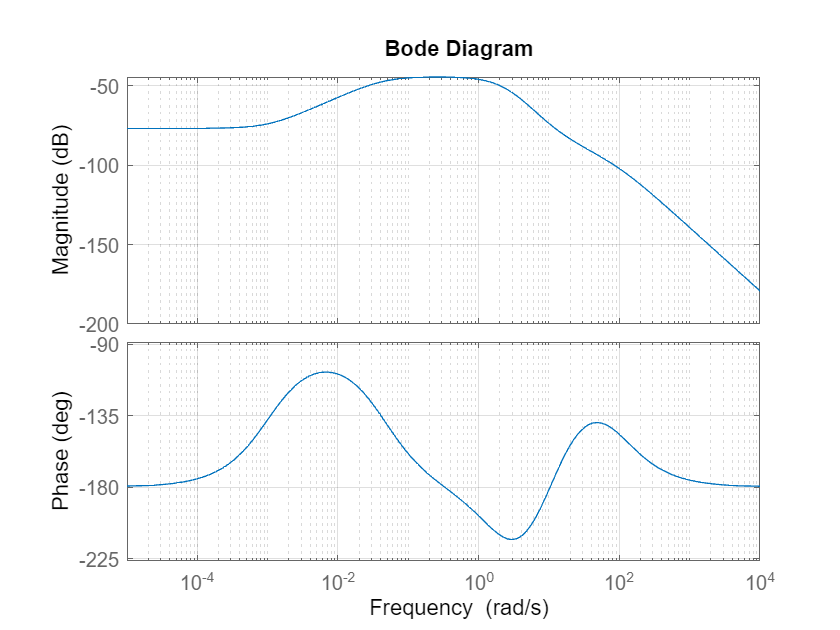

theeta = G_comp*G3;
bodeplot(theeta),grid

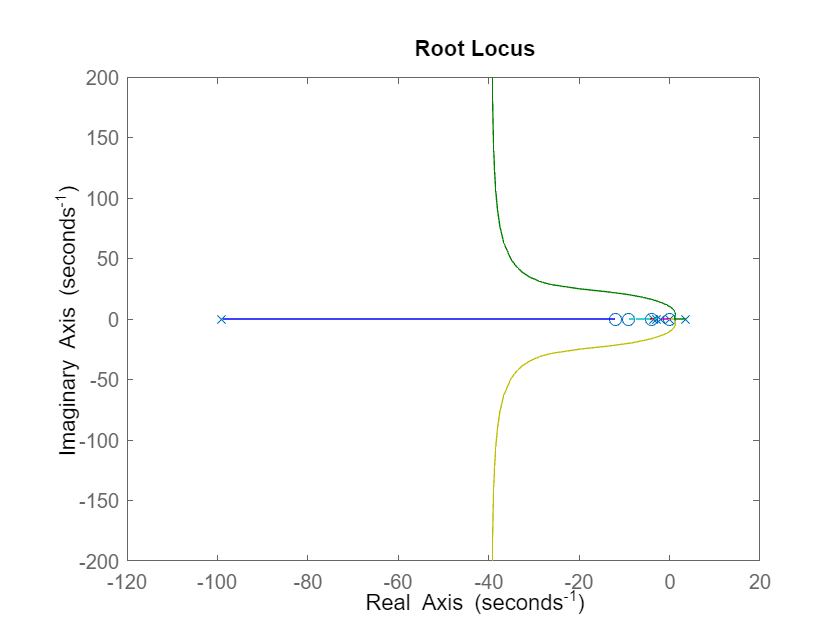

rlocus(theeta)

%Q3)
%Contrallability and Observability
Qa = [0 1 0; A -F B; 0 0 -H]; % 'A' matrix in state-space model
Qb = [0  -C G];               
QbT = transpose(Qb);          % 'B' matrix in state-space model
Qcc = [0 E 0];                % 'C' matrix in state-space model
QccT= transpose(Qcc);
%Controllabilty Matrix and the code to check controllabilty
Qc = [QbT Qa*QbT Qa*Qa*QbT];
if rank(Qc) == 3 % We have three state variables with which we obtained a 3X3 matrix, so our maximumm/full rank is 3 
    disp("System is Controllable since the rank of Qc is full");
else
    disp("System is not controllable since the rank of Qc is not full")
end

System is Controllable since the rank of Qc is full


%Observability Matrix and the code to check observabilty
Qd = [QccT Qa*QccT Qa*Qa*QccT];
if rank(Qc) == 3
    disp("System is Observable since the rank of Qd is full ");
else 
    disp("System is not Observable since the rank of Qd is full")
end

System is Observable since the rank of Qd is full 


%Q4) Canonical form and Modal canonical form
Qa = [0 1 0; A -F B; 0 0 -H]; % 'A' matrix in state-space model
Qb = [0; -C; G];               % 'B' matrix in state-space model
Qcc = [0 E 0];                % 'C' matrix in state-space model
Qf  = 0;                      % 'D' matrix in state-space model
QccT= transpose(Qcc);
sys = ss(Qa,Qb,Qcc,Qf)

sys =
 
  A = 
              x1         x2         x3
   x1          0          1          0
   x2      12.83  -0.001837    0.02296
   x3          0          0   -0.04444
 
  B = 
              u1
   x1          0
   x2  -0.009184
   x3    0.01736
 
  C = 
          x1     x2     x3
   y1      0  14.42      0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


eig_values = eig(sys)

eig_values =     3.5810
   -3.5828
   -0.0444


csys = canon(sys,'companion')

csys =
 
  A = 
             x1        x2        x3
   x1         0         0    0.5702
   x2         1         0     12.83
   x3         0         1  -0.04628
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
            x1       x2       x3
   y1  -0.1324  0.00599   -1.699
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


mcys = canon(sys,'modal')

mcys =
 
  A = 
             x1        x2        x3
   x1     3.581         0         0
   x2         0    -3.583         0
   x3         0         0  -0.04444
 
  B = 
            u1
   x1  -0.2176
   x2   -0.223
   x3  0.03495
 
  C = 
              x1         x2         x3
   y1     0.3005     0.3006  0.0005697
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


%Q5) Choose desired poles and obtain corresponding value of gain K using ACKER command
P_star = [-1 -0.2 -2]; %Our desired poles
K = acker(Qa,Qb,P_star)

K = 1.0e+03 *

   -1.6797   -0.3515   -0.0043
